# **Euler Differentiation Method Code**

## **Input**

n=10;   % number of iteration
a=0;       %interval start value
b=5;      % interval end value
h=(b-a)/n;     % step size 

## x discretization

%% x discretization
x=a :h:b;
y=zeros(size(x));

## Initial Condition

%% initial condition
x(1)=0;     y(1)=1;

## Differential Eq. y'=f(x,y)=e^(2x)+ln(y)

%% Differential Eq.     Y =f(x, y)=
% the loop to solve the DE
fprintf("n       x         y");

n       x         y

for i=1: n
    fprintf('%2i %9.5f %10f\n',i ,x(i), y(i)); %printing the data
    ln_y= log(y(i)); %calculate ln(y)
    f=exp(2*x(i))+ln_y; %calculate f
    y(i+1) = y(i) + h * f ; %Euler method
end

 1   0.00000   1.000000
 2   0.50000   1.500000
 3   1.00000   3.061873
 4   1.50000   7.315915
 5   2.00000  18.353710
 6   2.50000  47.107700
 7   3.00000 123.240498
 8   3.50000 327.361964
 9   4.00000 878.574076
10   4.50000 2372.442220


## Visualization

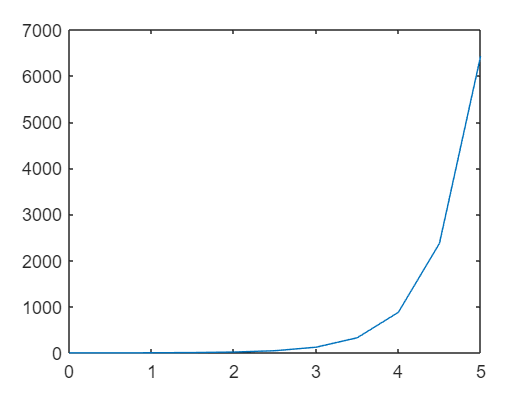

%%Visualization (for a graph-like solution)
figure(1)
plot (x , y)